# Setup

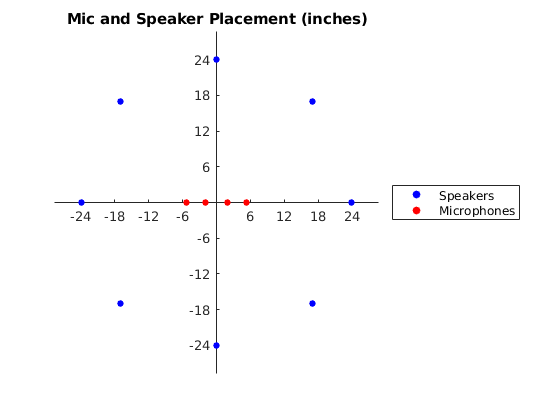

% Dimensions in inches
mics = [
    % x, y
    -5.375, 0 % left-to-right makes this easiest to think about (channels are LLRR)
    -1.875, 0 % 3.5 inch spacing, centered at 0
    1.875, 0
    5.375, 0
    ];

R = 24;  % inches
speakers = 0:pi/4:7*pi/4;  % 8 evenly spaced speakers in a circle. 1 is directly to the right.
speakers_x = R*cos(speakers);
speakers_y = R*sin(speakers);

% Visualize placement
handle_m = scatter(mics(:, 1), mics(:, 2), 25, 'red', 'filled');
hold on;
handle_s = scatter(speakers_x, speakers_y, 25, 'blue', 'filled');
xlim([-1.2 * R, 1.2 * R]);
ylim([-1.2 * R, 1.2 * R]);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
xticks(-R:6:R);
yticks(-R:6:R);
legend([handle_s handle_m],'Speakers','Microphones', 'Location', 'EastOutside');
title('Mic and Speaker Placement (inches)');


num_mics = size(mics, 1);
num_speakers = length(speakers);

% calculate the distance from each speaker to mic
distances = zeros(num_mics, num_speakers);
for i=1:length(mics)
    mic = mics(i, :);
    for j=1:num_speakers
        distances(i, j) = norm(mic - [speakers_x(j), speakers_y(j)]);
    end
end

% convert to time differences
pace_of_sound = 74.0524781;  % in microseconds per inch (lol)
time_differences = pace_of_sound * distances;

## Demo begins here

% demonstration (all fs should be the same)
% fruit: HINT/2_08.WAV
% picture: HINT/1_09.WAV

[main_signal, fs] = audioread('Recordings/HINT/1_09.WAV');
main_signal = main_signal * db2mag(0); % adjust to reach desired SNR

samples_per_microsecond = fs * 1e-6;  % convert time to samples
sample_differences = round(samples_per_microsecond * time_differences);

main_db = get_db(main_signal);
quad_main = generate_output(main_signal, sample_differences, Direction.N);
audiowrite('Recordings/Geometry/intermediate/output_N.wav', quad_main, fs);

% for white noise
noise = wgn(size(main_signal, 1), size(main_signal, 2), main_db+16);
noise_db = get_db(noise);
quad_noise_l = generate_output(noise, sample_differences, Direction.E);
quad_noise_r = generate_output(noise, sample_differences, Direction.SE);
audiowrite('Recordings/Geometry/intermediate/output_E.wav', quad_noise_l, fs);

% For babble noise
% [noise_right, ~] = audioread('Recordings/Other/AMAC_babble_right.wav');
% quad_noise_r = generate_output(noise_right(200000:end), sample_differences, Direction.SE);
% audiowrite('Recordings/Geometry/intermediate/output_SE.wav', quad_noise_l, fs);
% 
% [noise_left, ~] = audioread('Recordings/Other/AMAC_babble_left.wav');
% quad_noise_l = generate_output(noise_left(200000:end), sample_differences, Direction.E);
% audiowrite('Recordings/Geometry/intermediate/output_E.wav', quad_noise_l, fs);
% noise_db = get_db(noise_left + noise_right);
initial_snr = main_db - noise_db

initial_snr = -15.9889


len = size(quad_main, 1);
result = quad_main + quad_noise_l(1:len, :) + quad_noise_r(1:len, :);
audiowrite('Recordings/Geometry/result.wav', result, fs);